# **ISS Live Script**

This Matlab Live Scripts summarizes the functions developed in order to analyse the spatial profiles derived from ISS. However, they can be applied to other spatial technologies, since the only requirement they present is the spatial distribution of genes in 2D, together with a DAPI background image representing the nuclei. 

## Loading the data

The path to the file containing the spatial expression of our genes of interest is saved in decoded_file. The background used, in our case DAPI, is saved in **image**. We extract the coordinates from the decoded_file using the function **ISS_getspots** and we save it on a SPOTS object. This SPOTS object contains the main information regarding Gene expression, its location, background image and output location. 

decoded_file = 'G:\Tools-master\Analysis_functions\QT_0.4_details_noNNNN_ALL.csv';
image = 'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif';    % important for size
scale=1;
%% do not modify
% load
SPOTS=ISS_getspots(decoded_file);
SPOTS.image=image;
SPOTS.scale=scale;
SPOTS.output_directory='G:\outputfolder';
mkdir(SPOTS.output_directory);

## Gene Density maps

The function ISS_GeneDensity creates a density map for the desired gene. We need to specify a Bandwidth for the density map. 


%ISS_GeneDensity plots the density of 1 gene
genes_density = {'SIRT2'}; 
bandwid = 200;   % in original scale
ISS_GeneDensity(SPOTS, genes_density, bandwid)


ISS_OverlayTwoDensities generates a 2D density map with the density of 2 genes. Two maps are actually generated, one with Smooth kernel and another one without.

%ISS_OverlayTwoDensities overlays 2 densities
genes_density = {'30', '21'};       % first in red, second in cyan
bandwid=100

bandwid = 100

ISS_OverlayTwoDensities(CELLSHIERARCHICAL,genes_density,bandwid);

Error using cell/unique (line 85)
Cell array input must be a cell array of character vectors.

Error in ISS_OverlayTwoDensities (line 14)
[uNames, ~, iName] = unique(name);

## Dissimilarity test 

Dissimilarity test search for coexpression of genes, taking into account a different number of counts on each case. We need to specify the minumum number of genes per bin/cell, together with 

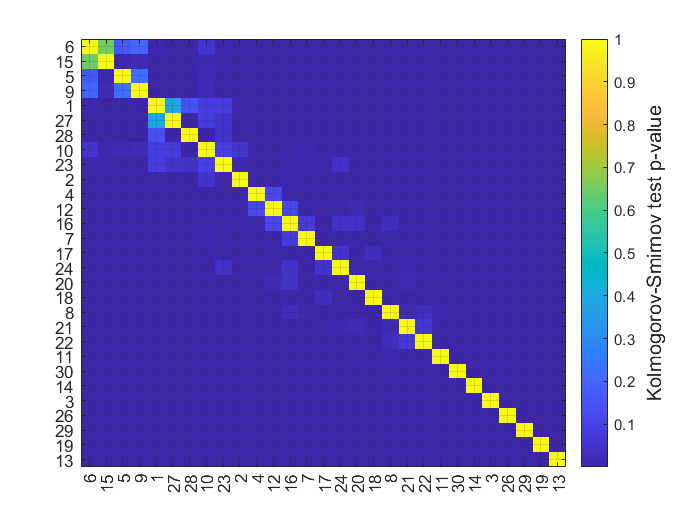

% ISS_DissimilarityTest test for dissimilarity
    %varargin1 is minimum number of genes per cell
    % varargin2 is hexbin size
 ISS_DissimilarityTest(CELLSHIERARCHICAL,5,10);

## **Find Neighbors **

 ISS_FindNeighbors_screen_randomization(SPOTS)

## Search AND regions

ANDgenes= {'SIRT2', 'WASF1'}; 
ISS_SearchANDRegions(SPOTS,ANDgenes);

## Search for regions with Similarity

transcripts={'SIRT2', 'WASF1'};

ISS_A_B_neighbors(SPOTS,transcripts);

# **Segmentation techniques**

## Segmenting cells

ISS_DAPI segmentation performs 

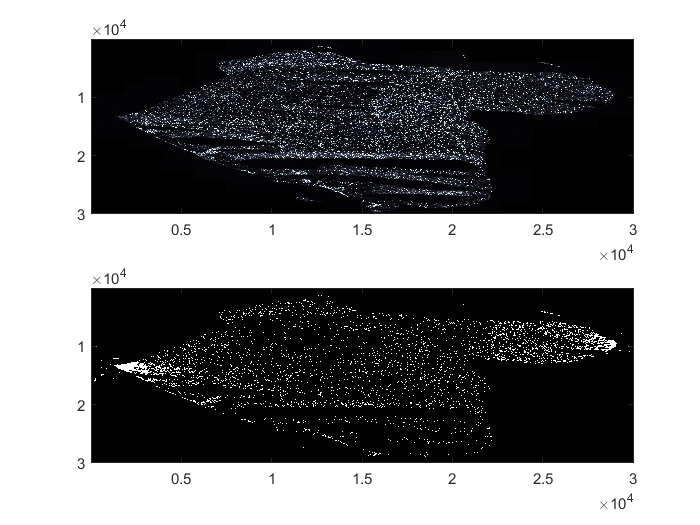

Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0.000000
Threshold = 0

XY = 	1.0e+04 *

    1.5179    0.0106
    1.5243    0.0100
    1.5271    0.0100
    1.5401    0.0102
    1.5415    0.0101
    1.5428    0.0101
    1.5671    0.0107
    1.5790    0.0100
    1.5814    0.0101
    1.5959    0.0112


percent=95;
[CellMap,blobs,XY]=ISS_DAPI_segmentation(SPOTS,percent);

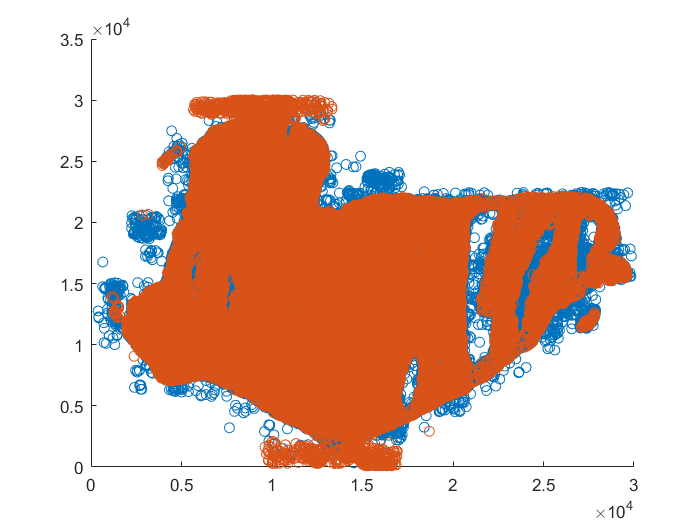

%XY=fliplr(vertcat(regionprops(CellMap).Centroid));

ISS_plotCellReads(SPOTS,CellMap)
[TOTAL,EXPRESSIONMAT,CELS]= ISS_assign_gene_to_cell(SPOTS,CellMap,XY);

## Creating overlapping means

We include on 2nd position distance and on 3rd radius

[OUTPUT] =ISS_OverlappingBins(SPOTS,200,800)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



i = 1

OUTPUT = struct with fields:
           exp: [14819×71 double]
           loc: [14819×2 double]
      genename: {71×1 cell}
    hexbinsize: 60


## RGB-Tsne representations

### **Tsne representation **

hexbin_size=40;
minimum_expression=100

minimum_expression = 100

ISS_tsneRGB(OUTPUT,SPOTS,minimum_expression); %EXPRESSIONMAT, SPOTS

Error using ISS_tsneRGB (line 10)
'Homo sapiens ATPase Na+/K+ transporting subunit alpha 2 (ATP1A2)' is longer than the maximum allowed length for a table variable name.

### Create a subset of your genes

Selection of a subset of genes

MATSEL.genename=EXPRESSIONMAT.genename(1:68);
MATSEL.exp=EXPRESSIONMAT.exp(:,1:68);
MATSEL.loc=EXPRESSIONMAT.loc;
MATSEL.hexbinsize=EXPRESSIONMAT.hexbinsize;


# Working with expression matrix 

This includes segmented data and binned data

## Hierarchical clustering data

Hierarchical custering performs a clustering based on a hierarchical strategy, by dividing data in binary categories consecutively. In this case, the number of categories desired needs to be specified by the user. 

CELLSHIERARCHICAL= ISS_hierarchical_clustering(MATSEL,SPOTS,30)

CELLSHIERARCHICAL = struct with fields:
    matrixcount: [39625×68 double]
       geneames: {68×1 cell}
           name: [1×39625 double]
            pos: [39625×2 double]
          image: 'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'
          scale: 1


This part plots the overall gene expression on top of the cell-type distribution plot. 

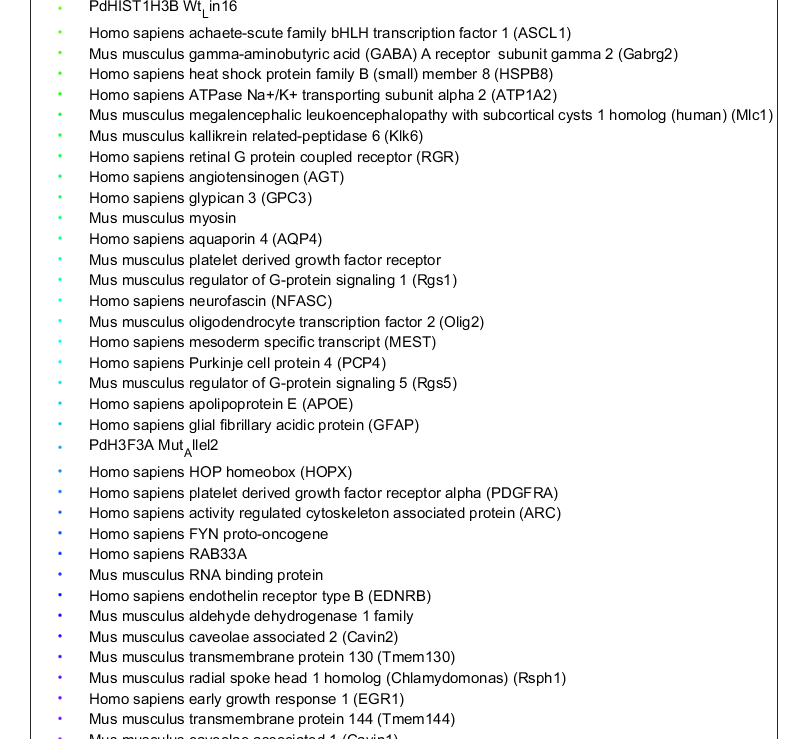

hold on 
gscatter(SPOTS.pos(:,1),SPOTS.pos(:,2),SPOTS.name);
hold on
 RGB=rgbscale(CELLS.Probabilities(:,1:3));
 %gscatter(CELLS.pos(:,1),CELLS.pos(:,2),CELLS.name(1:end,:))
 scatter(CELLS.pos(:,1),CELLS.pos(:,2),10,RGB(1:end-1,:),'filled');

# PCISEQ

PCIseq performs cell type assigment using single cell RNAseq and assuming that the sample contains the same cell types than the scRNAseq dataset. First we need to define a region. 

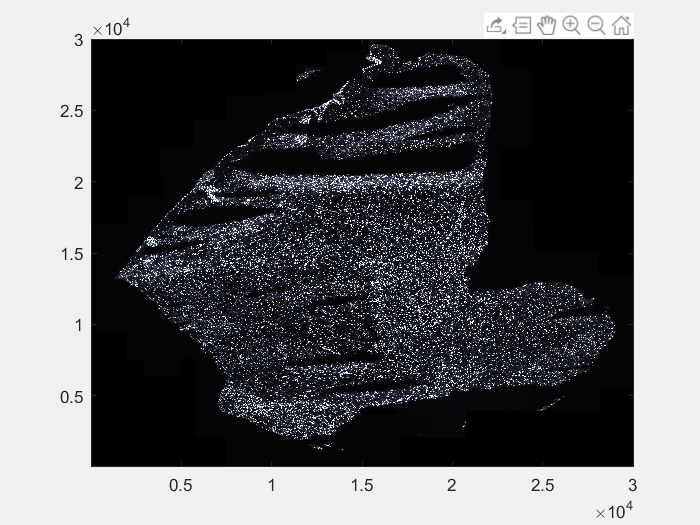

BigDapiImage = imread(SPOTS.image);
figure(707);
imagesc(min(BigDapiImage,prctile(BigDapiImage(:),98)));
colormap(bone);
set(gca, 'YDir', 'normal');
[~, xpoly, ypoly] = roipoly;

SPOTS.CellCallRegionYX=[ypoly,xpoly];


Then, we load the scRNAseq data already clustered on our gSet object. This will be used as an input in pciSeq 

Remember to load o to path






load E:\pciSeq\Data\AllSections\gSetCA1all.mat;
%CLUSTERED DATA ~ human cortex 
gSet.GeneExp=readmatrix('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
nam=readcell('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
namclust=readcell('H:\hm_brain_SBH_small\cortex_scRNAseq\Human_cortex_scRNAseq_dataset.csv');
gSet.GeneExp=gSet.GeneExp(:,2:end);
gSet.GeneExp=gSet.GeneExp';
gSet.GeneName=nam(2:end,1);
gSet.Class=namclust(1,2:end);
gSet.CellName=gSet.Class(1:size(gSet.Class,2));
gSet.nGenes=size(gSet.GeneExp,2);
gSet.nCells=size(gSet.GeneExp,1);



This is gSet for DIPG

load E:\pciSeq\Data\AllSections\gSetCA1all.mat;
gSet.GeneExp=readmatrix('G:\DIPG pciseq\expressionmatrix_selected.csv');
gSet.GeneExp=gSet.GeneExp(:,3:end);
nam=readcell('G:\DIPG pciseq\expressionmatrix_selected.csv');
gSet.GeneName=nam(2:end,2);
namclust=readcell('G:\DIPG pciseq\metadata_selected.csv');
gSet.Class=namclust(2:end,4);
gSet.CellName=gSet.CellName(1:size(gSet.Class,1));
gSet.nGenes=size(gSet.GeneExp,2);
gSet.nCells=size(gSet.GeneExp,1);
%THIS LINE IS FOR CONSIDERING CELL TYPE AS INDIVIDUAL CLASSES
%gSet.Class=gSet.CellName;

pciseq specific sample

gSet.GeneExp=readmatrix('G:\DIPG pciseq\scDATAspecifictumorDIPG.csv');
gSet.GeneExp=gSet.GeneExp(:,2:end);
nam=readcell('G:\DIPG pciseq\scDATAspecifictumorDIPG.csv');
gSet.GeneName=nam(2:end,1);
gSet.Class=nam(1,2:end);
gSet.CellName=gSet.CellName(1:size(gSet.Class,2))';
gSet.nGenes=size(gSet.GeneExp,1);
gSet.nCells=size(gSet.GeneExp,2);

Running PCIseq itself

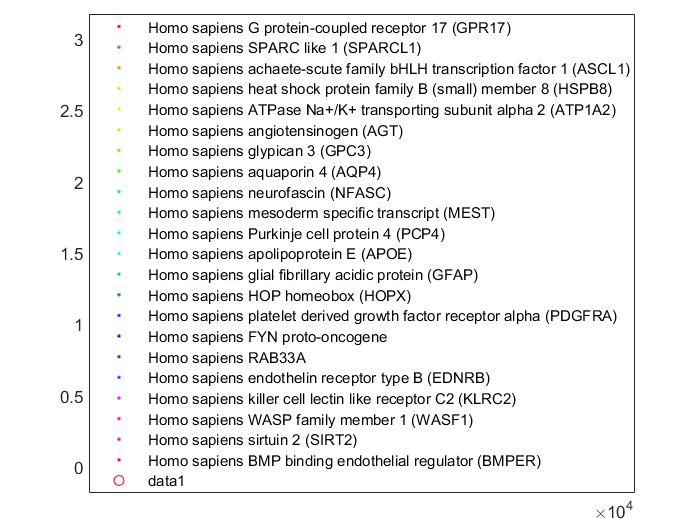

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

Error in ISS_pciseq (line 82)
ClassNames = vertcat(unique(gSet.Class, 'stable'),{'Zero'});

 CELLS = ISS_pciseq(SPOTS,CellMap,gSet)

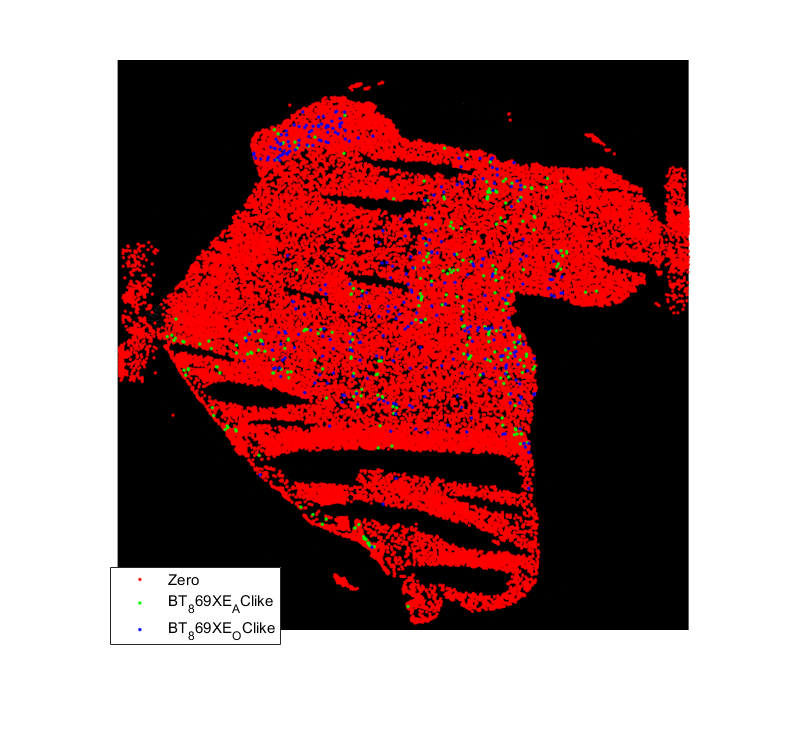

figure
 imshow(imread(SPOTS.image))
 hold on
 %RGB=rgbscale(CELLS.Probabilities(:,1:3));
 gscatter(CELLS.pos(:,1),CELLS.pos(:,2),CELLS.name(1:end,:))

 %scatter(CELLS.pos(:,1),CELLS.pos(:,2),10,RGB(1:end-1,:),'filled');

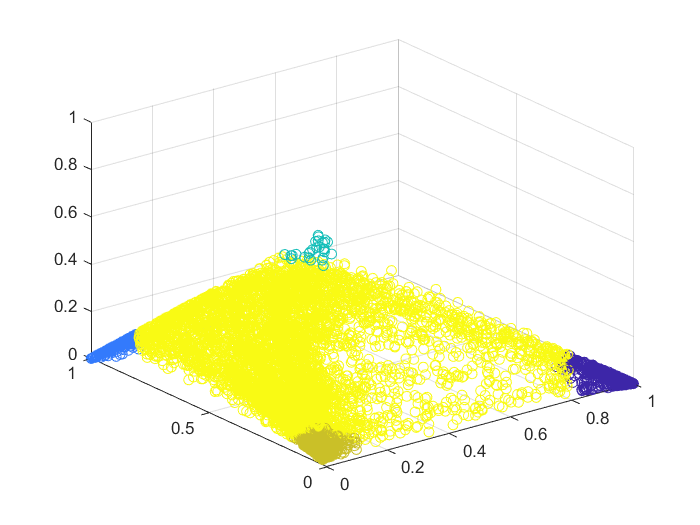

figure
scatter3(CELLS.Probabilities(1:end-1,1),CELLS.Probabilities(1:end-1,2),CELLS.Probabilities(1:end-1,3),[],categorical(CELLS.name(1:end,1))');

Selection based on CELS

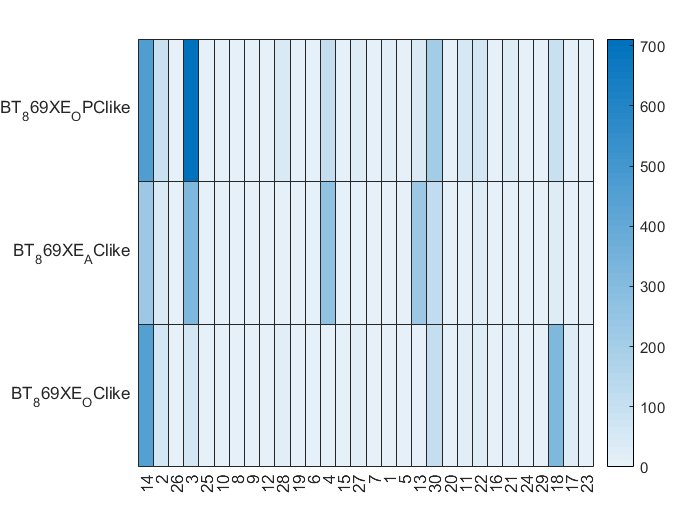

h =   HeatmapChart with properties:

        XData: {30×1 cell}
        YData: {3×1 cell}
    ColorData: [3×30 double]

  Show all properties


SELECTED.clusters=cellstr(num2str(CELLSHIERARCHICAL.name'));
SELECTED.pos=CELLS.pos(CELS,:);
SELECTED.name=CELLS.name(CELS,:);

[celltypecor,n,a,labels]=crosstab(SELECTED.name,SELECTED.clusters);

figure
XC=unique(SELECTED.clusters);
YC=unique(SELECTED.name);
h = heatmap(labels(:,2),labels(2:4,1),celltypecor(2:4,:))

#### Heatmap on PCISEQ

Plotting a heatmap of differentially expressed clusters

     1

     2

     3

     4

     5

     6



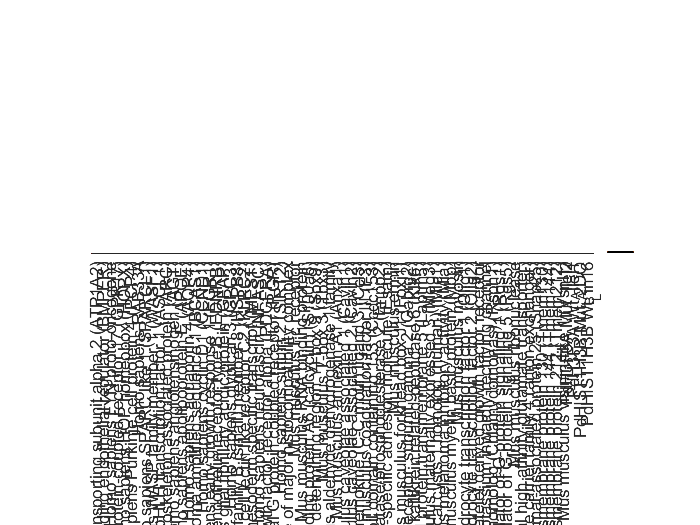

CANCERCT=ismember(CELLSHIERARCHICAL.name,[3,4,13,17,18,30]);
CANCERMAT.exp=EXPRESSIONMAT.exp(CANCERCT,:);
CANCERMAT.loc=EXPRESSIONMAT.loc(CANCERCT,:);
CANCERMAT.genename=EXPRESSIONMAT.genename;


ISS_heatmap_cluster(CANCERMAT,CELLSHIERARCHICAL.name(CANCERCT)')

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30



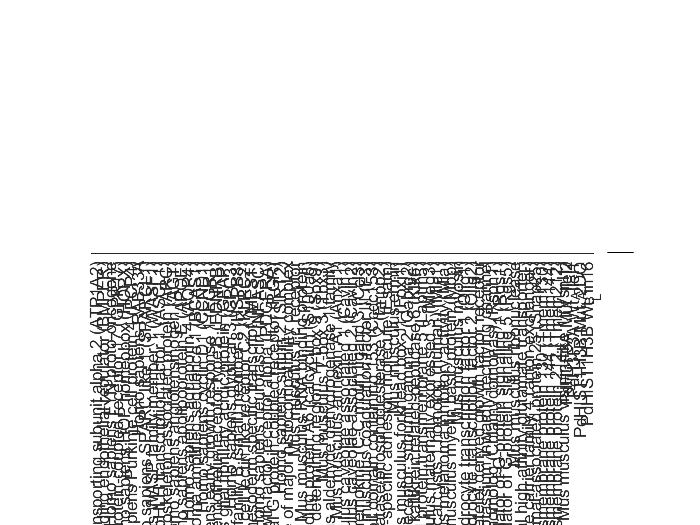

ISS_heatmap_cluster_rawcounts(EXPRESSIONMAT,CELLSHIERARCHICAL.name')

%ISS_heatmap_cluster(EXPRESSIONMAT,SELECTED.name')

## ROI selection

loading image..


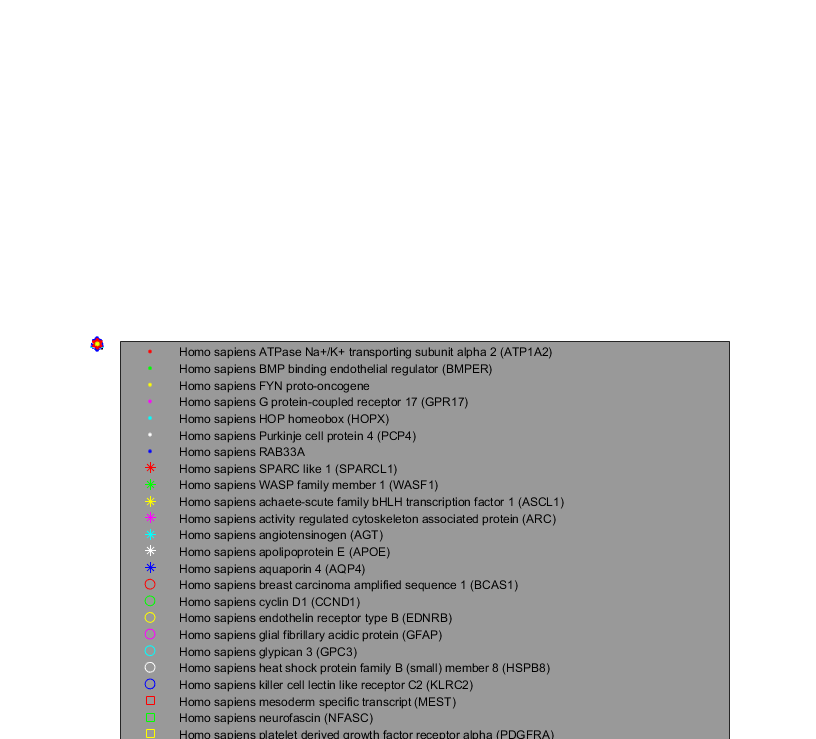

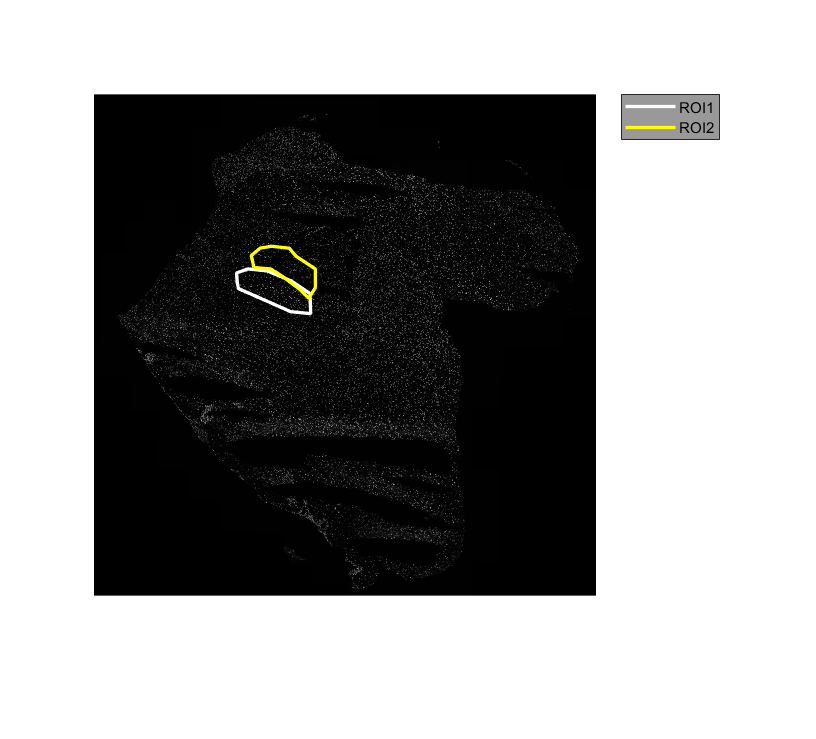

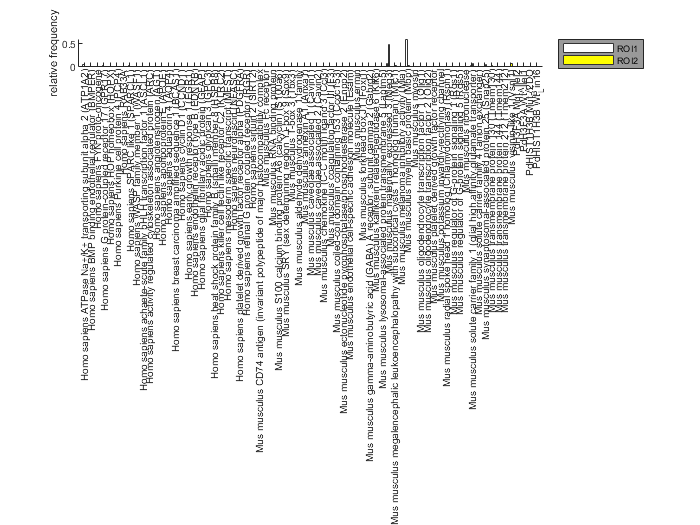


output_directory='G:\Tools-master\Visualization tools\Analize Region of Interests\ROI';
roi_number=2;
%LAST TWO TERMS CAN BE IN OR OUR DEPENDING IF YOU WANT TO SELECT BY DENSITY
%(adding 'Mus musculus myelin basic protein (Mbp)',100)
%OR DAPI 
roi_number=2;
[INROI,ROI_borders] = ISS_ROI_draw_onImage(SPOTS,output_directory,roi_number,'Mus musculus myelin basic protein (Mbp)',100);

Now we select ROI based on density 

-THIS IS SOMETHING THAT CAN BE ADDED 

## **GRADIENT ANALYSIS**

We define a gradient expression based on a ROI defined by ourselves

limits=800;
bandwidth=100;
ISS_gradients(CELLS,limit,bandwidth)


Clustegram

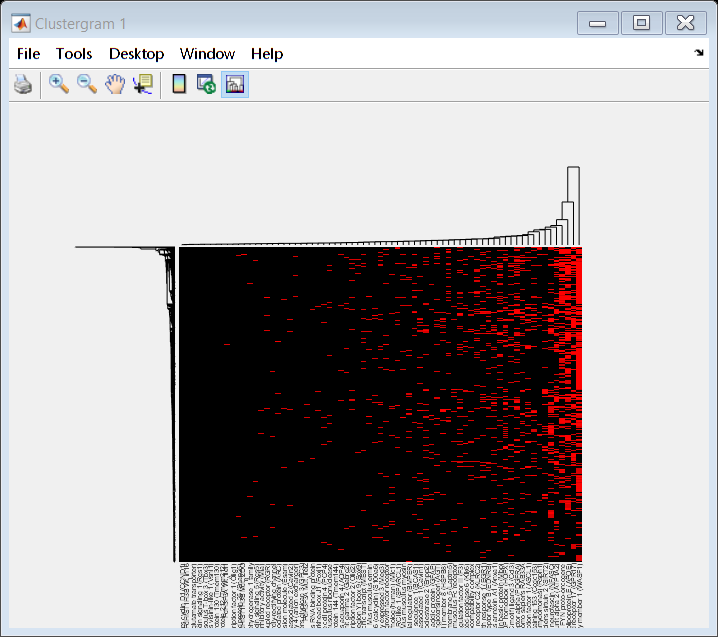

clustergram(EXPRESSIONMAT.exp, 'ColumnLabels', EXPRESSIONMAT.genename);

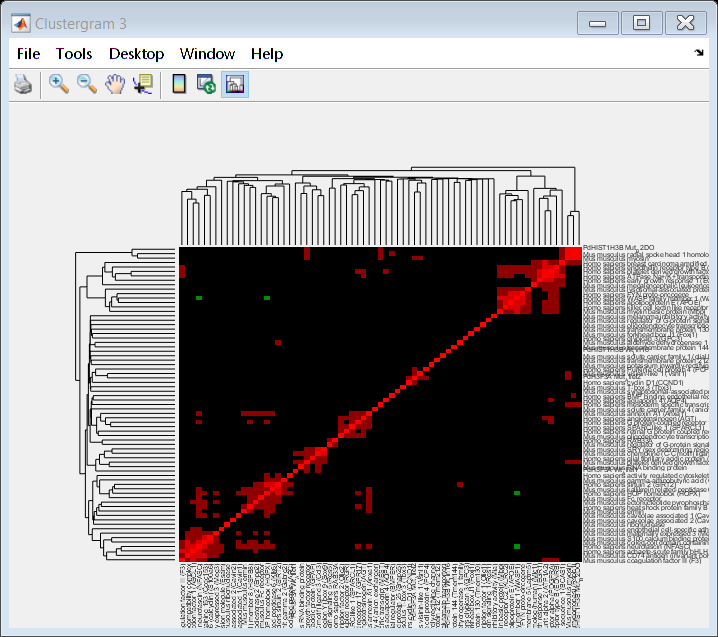

corelat=corr(EXPRESSIONMAT.exp);
clustergram(corelat, 'ColumnLabels', EXPRESSIONMAT.genename,'RowLabels', EXPRESSIONMAT.genename);

## Seach for the closest class in terms of expression

It calculates the density for all the genes/cells and it computes the correlation between them. 

NOTE: It can be a slow process. The bandwidth specified is a quite key parameter

[MEANDIST] =ISS_densities_correlation(CELLSHIERARCHICAL,bandwidth)

**HETEROGENEITY MAP**

CELLBINS=ISS_OverlappingBins(CELLSHIERARCHICAL,200,200)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



i = 1

CELLBINS = struct with fields:
           exp: [10002×30 double]
           loc: [10002×2 double]
      genename: {30×1 cell}
    hexbinsize: 60


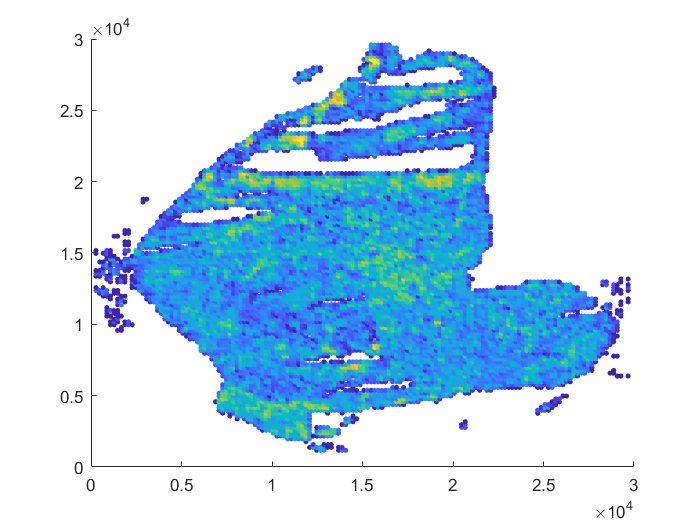

ISS_heterogeneity_map(CELLBINS,CELLSHIERARCHICAL)

## **INTEGRATING MORE THAN ONE OBJECT**